Plots kruppel trace at specific ap position (assumes kruppel traces were already loaded)

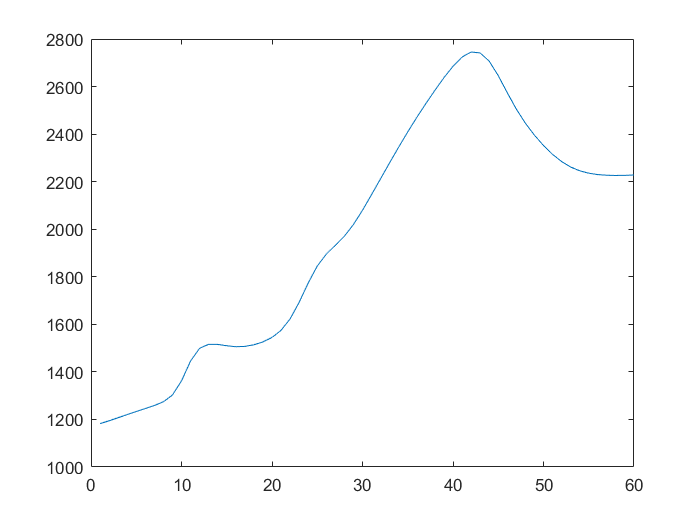


ap = 500;
figure();
plot(KrMov(1:end, ap));

Simulates kruppel eve2 in the case that kruppel just effects the transition rate matrix

% get kruppel traces

krup_traces = cell(1, 1000);
len_tr = 100;
idx = 1;
sets_to_use = [1 4:6 8:12];
data_path = '../dat/Kruppel_eve2_pass1/inference_traces_Kruppel_eve2_pass1_dT20.mat';
load(data_path);
set_struct = trace_struct_final(ismember([trace_struct_final.setID], sets_to_use));
set_struct = set_struct([set_struct.MeanAP] > 1);
set_struct = set_struct([set_struct.MeanAP] < 7);
while idx <= length(krup_traces)
    randidx = randi(length(set_struct));
    prot_trace = set_struct(randidx).protein_interp;
    if length(prot_trace) >= len_tr
        krup_traces{idx} = prot_trace(1:len_tr);
        idx = idx + 1;
    end
end

elong_time = 140;
time_res = 20;
points_per_trace = length(krup_traces{1});
num_traces = 500;
%krup_ks = [.0000000001, .00001]; %coop 1
krup_ks = [.1^16, .00001]; % coop 2
gen_ks = [.03, .05];
coop_coeff = 2;
rna_per_sec = [.0001, .2];
fluo_per_rna = 35;
MS2_rise_time = 40;
noise = 0;
[traces, traces_krup] = gen_kruppel_eve2_data(elong_time,time_res, points_per_trace,...
                            num_traces, krup_traces, coop_coeff,krup_ks, gen_ks, ...
                            rna_per_sec, fluo_per_rna,MS2_rise_time, ...
                            noise);

Simulates when kruppel turns off eve2 transcription

krup_traces = cell(1, 1000);
len_tr = 100;
idx = 1;
sets_to_use = [1 4:6 8:12];
data_path = '../dat/Kruppel_eve2_pass1/inference_traces_Kruppel_eve2_pass1_dT20.mat';
load(data_path);
set_struct = trace_struct_final(ismember([trace_struct_final.setID], sets_to_use));
set_struct = set_struct([set_struct.MeanAP] > 1);
set_struct = set_struct([set_struct.MeanAP] < 7);
while idx <= length(krup_traces)
    randidx = randi(length(set_struct));
    prot_trace = set_struct(randidx).protein_interp;
    if length(prot_trace) >= len_tr
        krup_traces{idx} = prot_trace(1:len_tr);
        idx = idx + 1;
    end
end

elong_time = 140;
time_res = 20;
points_per_trace = length(krup_traces{1});
num_traces = 1000;
coop_coeff = 2;
%kon_krup = .0000000002; % for  coop 1
kon_krup = .00000000000000004; % for coop 2
gen_ks = [.03, .05];
rna_per_sec = [.0001, .2];
fluo_per_rna = 350;
MS2_rise_time = 40;
noise = 0;
[traces, traces_krup] = gen_fatal_krup_data(elong_time,time_res, points_per_trace,...
                            num_traces, krup_traces, kon_krup, coop_coeff,gen_ks, ...
                            rna_per_sec, fluo_per_rna,MS2_rise_time, ...
                            noise);

Plots individual traces

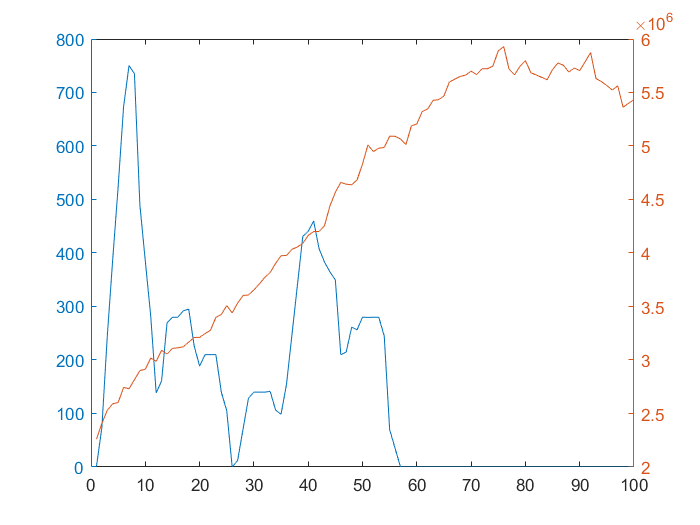

i = 83;
figure();
yyaxis left
plot(traces{i});
yyaxis right
plot(traces_krup{i});

Compiled simulated data into similar form of real data (so that I can run analysis scripts on it)

trace_struct_final = struct;
for i = 1:length(traces)
    trace_struct_final(i).fluo_interp = traces{i};
    trace_struct_final(i).protein_interp = traces_krup{i};
    trace_struct_final(i).time_interp = linspace(20, 1600,length(traces{i}));
    trace_struct_final(i).MeanAP = 3;
    trace_struct_final(i).setID = 1;
end

Plots cross correlation

addpath('utilies/');

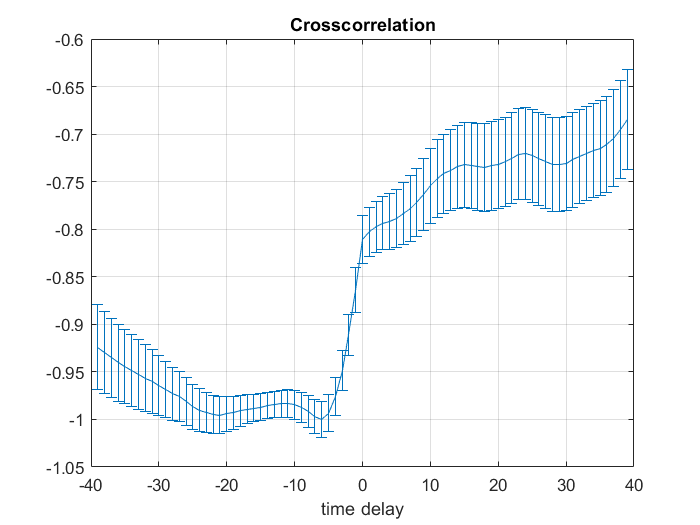


max_delay = 40;
corr = cross_corr_m_calc(traces, traces_krup, max_delay);
deriv1 = corr(2:end) - corr(1:end-1);
deriv2 = deriv1(2:end) - deriv1(1:end-1);
[stds, stds1, stds2] = corr_bootstraps(traces, traces_krup, max_delay, 100, 'm');
figure();
%plot(-max_delay + 1:max_delay - 1, corr)
errorbar(-max_delay + 1:max_delay - 1, corr, stds);
title('Crosscorrelation')
xlabel('time delay')
grid on

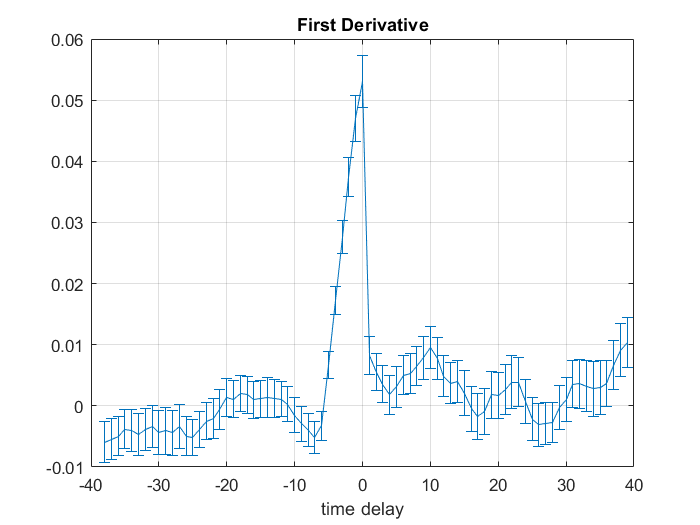


figure();
%plot(-max_delay + 2: max_delay - 1, deriv1);
errorbar(-max_delay + 2: max_delay - 1, deriv1, stds1);
title('First Derivative');
xlabel('time delay')
grid on

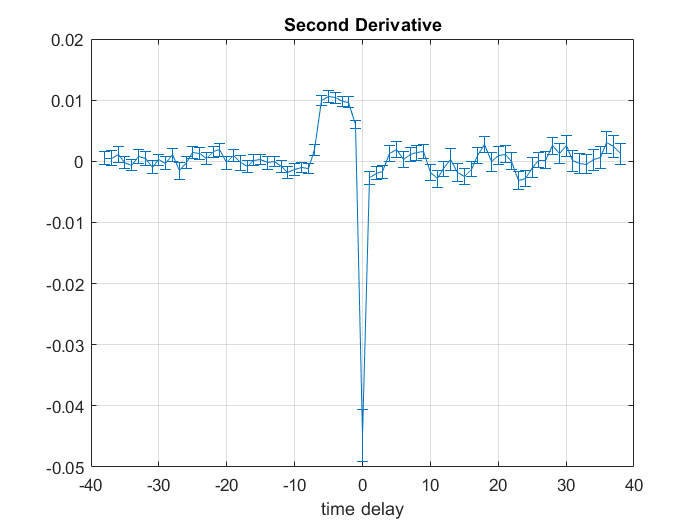


figure();
%plot(-max_delay + 2: max_delay - 2, deriv2);
errorbar(-max_delay + 2: max_delay - 2, deriv2, stds2);
title('Second Derivative');
xlabel('time delay')
grid on